# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.2  最优化

#### 3.2.17 核磁共振T2反演

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

## 共轭梯度法

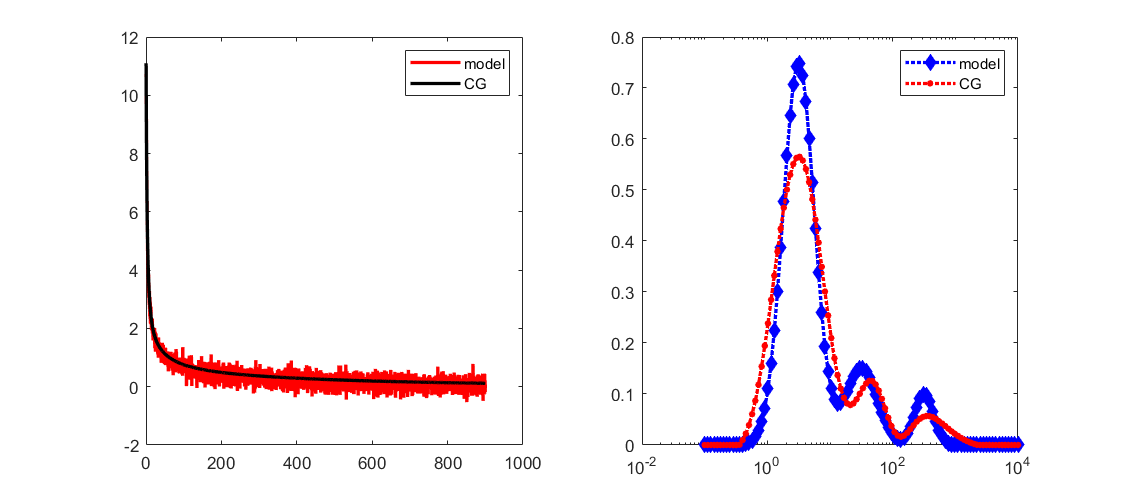

% 正演模型：三指数模型
clear;clc;close all;
% 基本参数
M = 3000;         
N = 100;       
Te = 0.3;
binset = logspace(-1, 4, N)';
t = Te*(1:M)';
% 正演回波衰减曲线
pos1 = 0.3;
pos2 = 0.5;
pos3 = 0.7;
dis = linspace(0, 1, N)';
model1 = gaussmf(dis, [0.05, pos1]);
model2 = gaussmf(dis, [0.05, pos2]);
model3 = gaussmf(dis, [0.03, pos3]);
T2 = 0.75*model1 + 0.15*model2 + 0.1*model3;
A = zeros(M,N);
%
for i = 1:M
    for j = 1:N
        A(i, j) = exp(-t(i) / binset(j));
    end
end
echo = A*T2;
% 回波加噪反演
per = 0.2;
noise = per*randn(M,1);
echo = echo + noise;
snr = echo(1)/(norm(noise)/sqrt(M-1));
T2dist = CGNE(A, echo, 1000);
% 拟合误差
y = A*T2dist;
ERR = norm(echo - y)/sqrt(M-1);
% 结果显示
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1)
plot(t, echo, 'r', t, y, 'k', 'LineWidth', 2)
legend('model', 'CG')
subplot(1, 2, 2)
semilogx(binset, T2, ':db', 'MarkerFaceColor', 'b', 'MarkerSize', 5, 'LineWidth', 2)
hold on
semilogx(binset, T2dist, ':or', 'MarkerFaceColor', 'r', 'MarkerSize', 2, 'LineWidth', 2)
legend('model', 'CG')
hold off

## CONTIN 算法

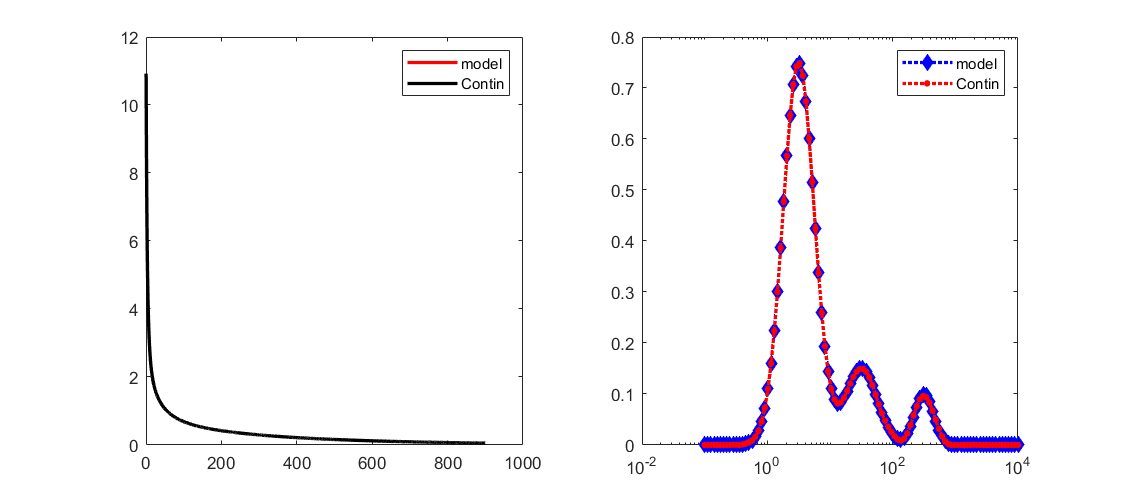

M = 3000;
N = 100;
TE = 1.2;
%
tim = zeros(M,1);
T2min = 0.01;
T2max = 10000;
bin = logspace(log10(T2min), log10(T2max), N)';   
for i = 1:M
    tim(i) = TE*i;
end
% Forward Modelling
pos1 = 0.3;
pos2 = 0.5;
pos3 = 0.7;
dis = linspace(0, 1, N)';
model1 = gaussmf(dis, [0.05, pos1]);
model2 = gaussmf(dis, [0.05, pos2]);
model3 = gaussmf(dis, [0.03, pos3]);
T2 = 0.75*model1 + 0.15*model2 + 0.1*model3;
A = zeros(M,N);
%
for i = 1:M
    for j = 1:N
        A(i, j) = exp(-t(i) / binset(j));
    end
end
echo = A*T2;
lemt = 0.00005;  
T2dist = ContinAlgorithm(A, echo, lemt);
y = A*T2dist;
% 结果显示
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1)
plot(t, echo, 'r', t, y, 'k', 'LineWidth', 2)
legend('model', 'Contin')
subplot(1, 2, 2)
semilogx(binset, T2, ':db', 'MarkerFaceColor', 'b', 'MarkerSize', 5, 'LineWidth', 2)
hold on
semilogx(binset, T2dist, ':or', 'MarkerFaceColor', 'r', 'MarkerSize', 2, 'LineWidth', 2)
legend('model', 'Contin')
hold off

function x = CGNE(A, b, km)
% A --- parameter matrix
% b --- measured data
% x  --- return inversion result
% km --- iteration times, default,km=1000 
% initial value
N = size(A,2);
i = 0;
err = 1e-6;
x = zeros(N,1);
r = b - A*x;
d0 = A'*r;
% 迭代
while norm(r)/norm(b) > err && i < km
    alpha = norm(A'*r)^2 / norm(A*d0)^2;
    x = x + alpha*d0;
    r = r - alpha*A*d0;
    d = A'*r;
    beta = norm(d)^2 / norm(d0)^2;
    d = d + beta*d0;
    d0 = d;
    i = i+1;
end
x(x < 0) = 0;
end


function x = ContinAlgorithm(A, b, lemt)
% Contin algorithm is used for T2 inversion.
% lemt is the regularization parameter;
% A is the kernal matrix, m*n;
% b is the measured data, m*1;
% Solve the problem:‖b-Ax‖^2+a^2‖Rx‖^2=min, subject to x>=0.
%%
n = size(A, 2);
rr = zeros(n, 1);
SS = zeros(n, n);
H1 = zeros(n, n);
HH = zeros(n, n);
%%
R = zeros(n + 2, n);
for i = 1:n
    R(i, i) = 1;
    R(i + 1, i) = -2;
    R(i + 2, i) = 1;
end
% R = diag(ones(1, n)) - 2*diag(ones(1, n - 1), -1) + diag(ones(1, n - 2), -2);
% QR decomposition is used
% The purpose is:‖Ax-b‖=min → ‖Kx-y‖=min
[q, r] = qr(A);
yy = q'*b;
y = yy(1:n);
C = r(1:n, 1:end);
%%
[~, H, Z] = svd(R);
for i = 1:n
    H1(i, i) = 1/H(i, i);
    HH(i, i) = H(i, i);
end
[Q, S, W] = svd(C*Z*H1);
r = Q'*y;
for i = 1:n
    SS(i, i) = sqrt(S(i, i)*S(i, i) + lemt*lemt);
    rr(i) = r(i)*S(i, i)/SS(i, i);
end
%
G = SS*W'*HH*Z';
x = lsqnonneg(G, rr);
end